# PID Controller Design with Pole Placement Method

Following is the symbolic math script to calculate the gain of the PID controller using the desired closed loop pole locations, also knows as pole placement method.

clc, clear, clf;
syms s Kp Ki Kd a b p1 p2 p3 K

Let us assume a systeme Transfer function without the PID controller

G = K / (s ^ 2 + a * s + b);

The characteristic equation of the closed loop system with PID controller

G_cs = collect((s ^ 2 + a * s + b) * s + K * (Kd * s ^ 2 + Kp * s + Ki), s)

$$G\_cs = s^{3}+\left(a+K\,\mathrm{Kd}\right)\,s^{2}+\left(b+K\,\mathrm{Kp}\right)\,s+K\,\mathrm{Ki}$$

Now let us assume the desired closed loop pole locations are -p1, -p2, and -p3, that make the desired characteristic equation as follows:

G_des = (s + p1) * (s + p2) * (s + p3);
G_des = collect(G_des, s)

$$G\_des = s^{3}+\left(p_{1}+p_{2}+p_{3}\right)\,s^{2}+\left(p_{3}\,\left(p_{1}+p_{2}\right)+p_{1}\,p_{2}\right)\,s+p_{1}\,p_{2}\,p_{3}$$

Equating the coefficients of the characteristic equation of the closed loop system with PID controller and the desired characteristic equation, we get:

eq1 = coeffs(G_cs, s) == coeffs(G_des, s);
% Solving the above equations, we get the values of Kp, Ki, and Kd as follows:
sol = solve(eq1, [Kp, Ki, Kd])

sol = struct with fields:
    Kp: (p1*p2 - b + p1*p3 + p2*p3)/K
    Ki: (p1*p2*p3)/K
    Kd: (p1 - a + p2 + p3)/K


Kp_s = simplify(sol.Kp)

$$Kp\_s = \frac{p_{1}\,p_{2}-b+p_{1}\,p_{3}+p_{2}\,p_{3}}{K}$$

Ki_s = simplify(sol.Ki)

$$Ki\_s = \frac{p_{1}\,p_{2}\,p_{3}}{K}$$

Kd_s = simplify(sol.Kd)

$$Kd\_s = \frac{p_{1}-a+p_{2}+p_{3}}{K}$$

Example: Let us assume a system with the following transfer function and design a PID controller using pole placement method.


$$G\left(s\right)=\frac{5}{s^2 +10\;s+20}$$


clear s Kp Ki Kd a b p1 p2 p3
s = tf('s');
G = 5 / (s ^ 2 + 10 * s + 20)


G =
 
         5
  ---------------
  s^2 + 10 s + 20
 
Continuous-time transfer function.


[num, den] = tfdata(G);
a = den{1}(2);
b = den{1}(3);
[~, ~, K] = zpkdata(G);
zpk(G)


ans =
 
           5
  -------------------
  (s+7.236) (s+2.764)
 
Continuous-time zero/pole/gain model.


Let us design the controller with the Desired closed loop natural frequency, non-dominant pole

omega_n = 3;
p3 = 10 * omega_n;
i = 1;

for eta = 0.5:0.1:1
  p1 = (eta * omega_n + sqrt(1 - eta ^ 2) * omega_n * 1i);
  p2 = (eta * omega_n - sqrt(1 - eta ^ 2) * omega_n * 1i);

  Kp(i, :) = double(subs(Kp_s)); %#ok<*SAGROW>
  Ki(i, :) = double(subs(Ki_s));
  Kd(i, :) = double(subs(Kd_s));
  p1_n(i, :) = p1;
  p2_n(i, :) = p2;
  p3_n(i, :) = p3;
  zeta_n(i, :) = eta;
  C = pid(Kp(i, :), Ki(i, :), Kd(i, :));

Now let us check the step response of the closed loop system with the designed PID controller.

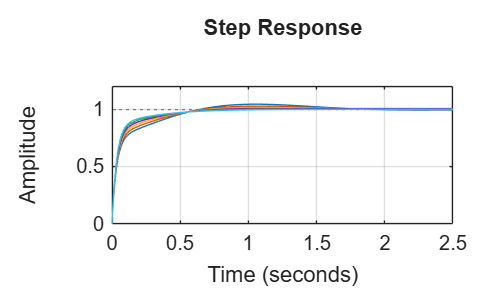

  sys_cl = feedback(C * G, 1);
  figure(1)
  hold on
  step(sys_cl)
  grid on

Now let us check the frequency response of the open loop system with the designed PID controller.

Gain Margin: Inf dB at Frequency: NaN rad/s


Phase Margin: 106.74 degrees at Frequency: 21.33 rad/s


The closed Loop system for zeta =  0.500000


ans =
 
  23 (s^2 + 3.435s + 11.74)
  -------------------------
    (s+30) (s^2 + 3s + 9)
 
Continuous-time zero/pole/gain model.


Gain Margin: Inf dB at Frequency: NaN rad/s


Phase Margin: 104.46 degrees at Frequency: 22.13 rad/s


The closed Loop system for zeta =  0.600000


ans =
 
  23.6 (s^2 + 4.11s + 11.44)
  --------------------------
   (s+30) (s^2 + 3.6s + 9)
 
Continuous-time zero/pole/gain model.


Gain Margin: Inf dB at Frequency: NaN rad/s


Phase Margin: 102.44 degrees at Frequency: 22.92 rad/s


The closed Loop system for zeta =  0.700000


ans =
 
  24.2 (s^2 + 4.752s + 11.16)
  ---------------------------
    (s+30) (s^2 + 4.2s + 9)
 
Continuous-time zero/pole/gain model.


Gain Margin: Inf dB at Frequency: NaN rad/s


Phase Margin: 100.63 degrees at Frequency: 23.71 rad/s


The closed Loop system for zeta =  0.800000


ans =
 
  24.8 (s^2 + 5.363s + 10.89)
  ---------------------------
    (s+30) (s^2 + 4.8s + 9)
 
Continuous-time zero/pole/gain model.


Gain Margin: Inf dB at Frequency: NaN rad/s


Phase Margin: 99.02 degrees at Frequency: 24.49 rad/s


The closed Loop system for zeta =  0.900000


ans =
 
  25.4 (s^2 + 5.945s + 10.63)
  ---------------------------
    (s+30) (s^2 + 5.4s + 9)
 
Continuous-time zero/pole/gain model.


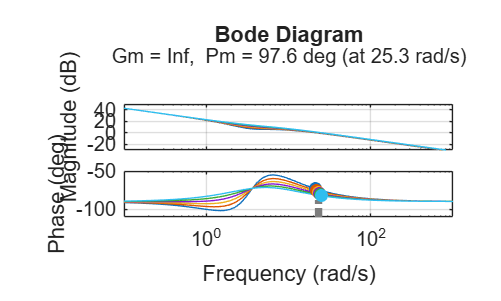

Gain Margin: Inf dB at Frequency: NaN rad/s


Phase Margin: 97.57 degrees at Frequency: 25.26 rad/s


The closed Loop system for zeta =  1.000000


ans =
 
  26 (s+3.672) (s+2.828)
  ----------------------
      (s+30) (s+3)^2
 
Continuous-time zero/pole/gain model.


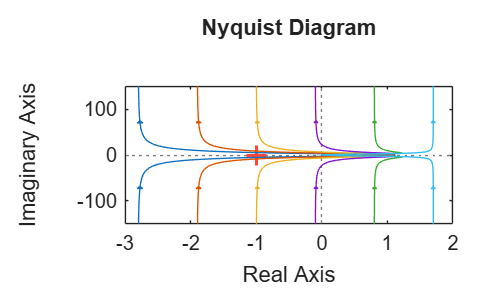

  figure(2)
  hold on
  margin(C * G)
  grid on
  [Gm(i, :), Pm(i, :), Wpc(i, :), Wgc(i, :)] = margin(C * G);
  fprintf('Gain Margin: %.2f dB at Frequency: %.2f rad/s\n', db(Gm(i, :)), Wpc(i, :));
  fprintf('Phase Margin: %.2f degrees at Frequency: %.2f rad/s\n', Pm(i, :), Wgc(i, :));
  fprintf('The closed Loop system for zeta =  %f',zeta_n(i,:))
  display(zpk(feedback(G*C,1)))
  figure(3), hold on;
  np = nyquistplot(C * G);
  i = i + 1;
end

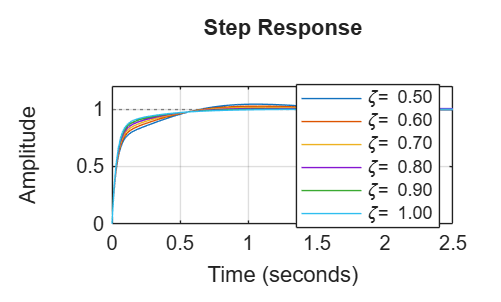


legendLabels = arrayfun(@(x) sprintf('\\zeta= %.2f', x), zeta_n, 'UniformOutput', false);
figure(1), legend(legendLabels, Location = "best"), hold off;
title('Step Response')

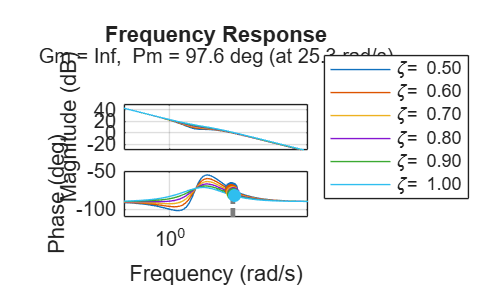

figure(2), legend(legendLabels, Location = "eastoutside"), hold off;
title('Frequency Response');

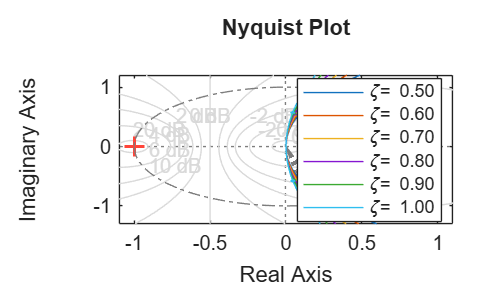

figure(3), legend(legendLabels, Location = "best"), hold off;
np.XLim = [-1.1, 1.1];
np.YLim = [-1.3, 1.2];
np.Characteristics.AllStabilityMargins.Visible = 'on';
grid("on")
title('Nyquist Plot');

tab = table(zeta_n, [p1_n, p2_n, p3_n], Kp, Ki, Kd, Gm, Pm, Wpc, Wgc, ...
  'VariableNames', {'Damping Ratio', 'Desired Closed Loop Poles', 'Kp', 'Ki', 'Kd', 'GM_dB', 'PM_deg', 'w_gc', 'w_pc'})

tab = 6×9 table
    Damping Ratio                Desired Closed Loop Poles                 Kp     Ki     Kd     GM_dB    PM_deg    w_gc     w_pc 
    _____________    _________________________________________________    ____    __    ____    _____    ______    ____    ______

         0.5         1.5+2.5981i        1.5-2.5981i              30+0i    15.8    54     4.6     Inf     106.74    NaN     21.328
         0.6         1.8+2.4i           1.8-2.4i                 30+0i    19.4    54    4.72     Inf     104.46    NaN     22.128
         0.7         2.1+2.1424i        2.1-2.1424i              30+0i      23    54    4.84     Inf     102.44    NaN     22.923
         0.8         2.4+1.